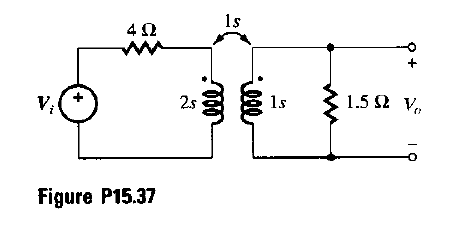

clc, clear, close all
format short g

syms w vi v0 i1 i2

s = j*w;

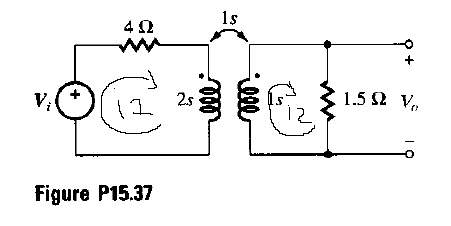

como la correinte i1 entra en un punto, y la correinyte i2 sale del punto entonces la tension tiene que ser contraria

%LTK
ec1 = simplify(-vi + 4*i1 + 2*s*i1 - s*i2 == 0)

$$ec1 = 2\,i_{1}\,\left(2+w\,\mathrm{i}\right)=\mathrm{vi}+i_{2}\,w\,\mathrm{i}$$

ec2 = simplify(i2*1.5 + s*i2 - s*i1 == 0)

$$ec2 = i_{2}\,\left(3+2\,w\,\mathrm{i}\right)=2\,i_{1}\,w\,\mathrm{i}$$

Ahora que tenemos las ecuaciones de malla, despejamos las variables vi y v0 para obtener la funcion de transferencia

trans_function = (-s*i2+s*i1)/(4*i1 + 2*s*i1 - s*i2)

$$tr\_f = \frac{i_{1}\,w\,\mathrm{i}-i_{2}\,w\,\mathrm{i}}{4\,i_{1}+2\,i_{1}\,w\,\mathrm{i}-i_{2}\,w\,\mathrm{i}}$$